**Compute the VaR Using the Exponential Weighted Moving Average Method (EWMA)**

The first two VaR methods assume that all past returns carry the same weight. The exponential weighted moving average (EWMA) method assigns nonequal weights, particularly exponentially decreasing weights. The most recent returns have higher weights because they influence "today's" return more heavily than returns further in the past. The formula for the EWMA variance over an estimation window of size $W_E$ is:


$$\hat{\sigma}^2_t=\frac{1}{c}\sum_{i=1}^{W_E}\lambda^{i-1} y^2_{t-i}$$


where $c$ is a normalizing constant:


$$c=\sum_{i=1}^{W_E}\lambda^{i-1} = \frac{1-\lambda^{W_E}}{1-\lambda}\quad\rightarrow \frac{1}{1-\lambda} ~ as ~ W_E\rightarrow\infty$$


For convenience, we assume an infinitely large estimation window to approximate the variance:


$$\hat{\sigma}^2_t\approx(1-\lambda)(y^2_{t-1}+\sum^{\infty}_{i=2}\lambda^{i-1}y^2_{t-i})=(1-\lambda)y^2_{t-1}+\lambda\hat{\sigma}^2_{t-1}$$


A value of the decay factor frequently used in practice is 0.94. 

Data = load('PortfolioReturns.mat');
Returns = Data.Returns;
DateReturns = Data.DateReturns;
Confidence = [95 99];

Define the estimation window as 250 trading days. The test window starts on the first day in 1996 and runs through the end of the sample.

SampleSize = length(Returns);
TestWindowStart      = find(year(DateReturns)==1996,1);
TestWindow           = TestWindowStart : SampleSize;

For a VaR confidence level of 95% and 99%, set the complement of the VaR level.

pVaR = 1 - Confidence/100;

## Compute the VaR Using the Exponential Weighted Moving Average Method (EWMA)

Lambda = 0.94;
Sigma2     = zeros(length(Returns),1);
Sigma2(1)  = Returns(1)^2;

for i = 2 : (TestWindowStart-1)
    Sigma2(i) = (1-Lambda) * Returns(i-1)^2 + Lambda * Sigma2(i-1);
end

Use the EWMA in the test window to estimate the VaR.

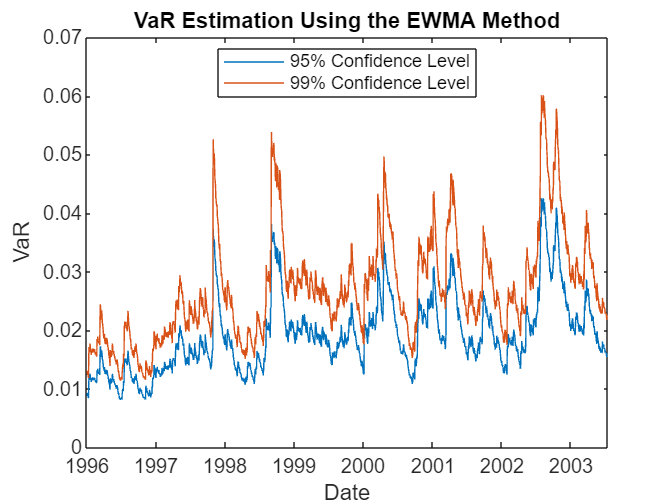

Zscore = norminv(pVaR);
% EWMA95 = zeros(length(TestWindow),1);
% EWMA99 = zeros(length(TestWindow),1);
Sigma = zeros(length(TestWindow),1);

for t = TestWindow 
    k     = t - TestWindowStart + 1;
    Sigma2(t) = (1-Lambda) * Returns(t-1)^2 + Lambda * Sigma2(t-1);
    Sigma(k) = sqrt(Sigma2(t));
%     EWMA95(k) = -Zscore(1)*Sigma;
%     EWMA99(k) = -Zscore(2)*Sigma;
end

EWMAVar = -Sigma*Zscore;

figure;
plot(DateReturns(TestWindow),EWMAVar)
ylabel('VaR')
xlabel('Date')
legend(Confidence + "% Confidence Level","Location","Best")
title('VaR Estimation Using the EWMA Method')